# H3

# Control de qualitat de peces de carn - Pol Fradera i Èric Riera

L’objectiu de la pràctica és detectar el percentatge de greix en unes llonzes.

close all
clear all
a = dir('./Chuletons/*.bmp');
nf = size(a);

noms = cell(nf);
percentatges_manuals = zeros(nf);
percentatges_auto = zeros(nf);
percentatges_otsu = zeros(nf);
percentatges_ptile = zeros(nf);

% aquests són els llindars que hem trobat a partir dels histogrames
llindar_manual_fons = [94 114 99 103 75 55 72 65 67 56 64 67 65 53];
llindar_manual_chuleton = [160 198 193 205 154 163 158 183 162 165 163 173 168 152];
figure
for i = 1:nf 
    filename = horzcat(a(i).folder,'/',a(i).name);
    I = imread(filename);
    noms{i} = convertCharsToStrings(a(i).name);
    imshow(I);
    drawnow

#### Retallat de la imatge

    rect = getrect();
    J = imcrop(I,rect);

### Binaritzatizació i percentatge de greix:

#### Llindar a partir de l'histograma

En aquest apartat mostrem l'histograma de la imatge per escollir el llindar per eliminar el fons, i seguidament mostrem l'histograma de la llonza per tal de trobar el llindar més adient per binaritzar la pròpia llonza. Els histogrames ens donaran un interval de possibles llindars.

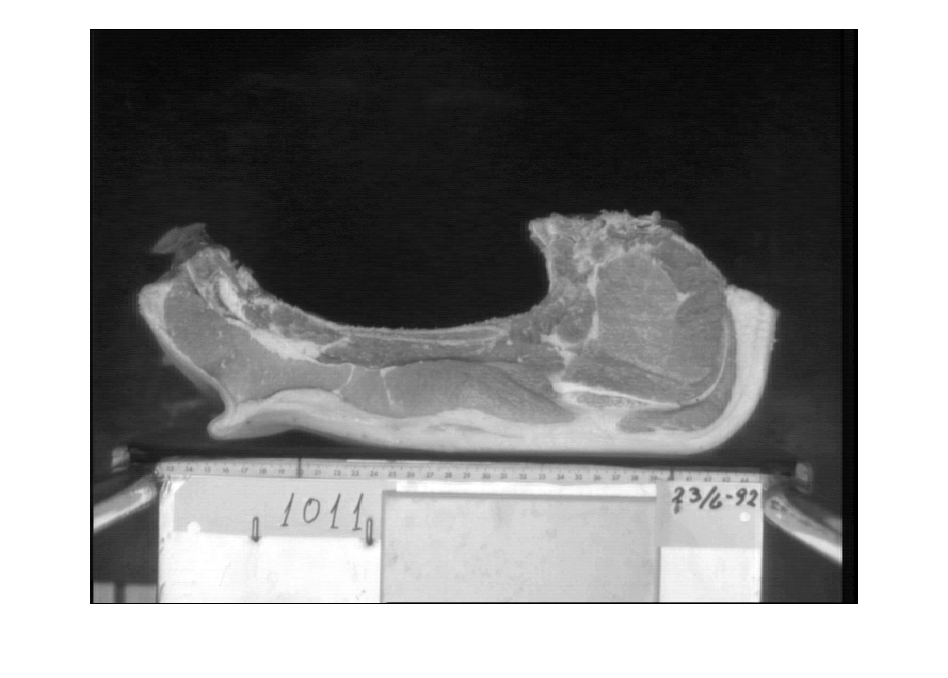

    histogram(J), title('Histograma de la imatge ' + convertCharsToStrings(a(i).name));

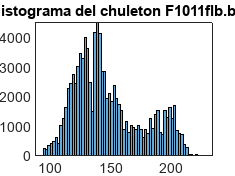

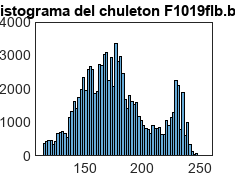

    figure
    chuleton = J;
    chuleton(J < llindar_manual_fons(i)) = 0; % imatge sense el fons
    
    llonza = chuleton > 0; % pixels de la llonza a 1
    histogram(chuleton(llonza)), title('Histograma del chuleton ' + convertCharsToStrings(a(i).name));

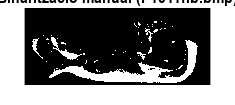

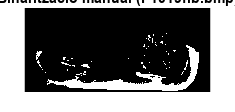

    figure

    greix = chuleton > llindar_manual_chuleton(i); % binaritzat de la llonza
    
    imshow(greix), title('Binarització manual (' + convertCharsToStrings(a(i).name) + ')')

    figure

    size_llonza = sum(sum(llonza));
    size_greix = sum(sum(greix));
    perc_greix_manual = (size_greix/size_llonza)*100;
    
    percentatges_manuals(i, 1) = perc_greix_manual;

#### Llindar de forma automàtica

En aquest apartat hem trobat els llindars de forma autòmatica utilitzant la funció graythresh que implementa l'Otsu thresholding.

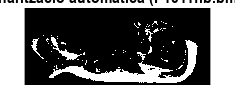

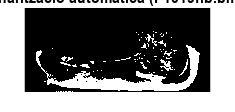

    llindar_llonza = graythresh(J)*256;
    chuleton = J;
    chuleton(J < llindar_llonza) = 0; % imatge sense el fons
    
    llonza = chuleton > 0; % pixels de la llonza a 1
    llindar_greix = graythresh(chuleton(llonza))*256;
    greix = chuleton > llindar_greix; % binaritzat de la llonza
    imshow(greix), title('Binarització automàtica (' + convertCharsToStrings(a(i).name) + ')')

    figure
    
    size_llonza = sum(sum(llonza));
    size_greix = sum(sum(greix));
    perc_greix_auto = (size_greix/size_llonza)*100;
    
    percentatges_auto(i, 1) = perc_greix_auto;

#### Llindar amb Otsu

En aquest apartat hem trobat els llindars mitjançant el mètode d'Otsu amb implementació pròpia.

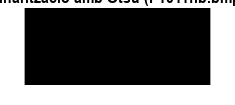

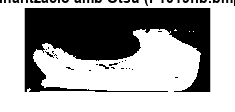

    h = imhist(J);
    [f c] = size(J);
    p = h/(f*c);
     
    m = (0:255).*p(1:256)';
    maxv = 0;
    maxt = 0;
    for t = 1:256
        w0 = sum(p(1:t));
        w1 = 1 - w0;
        nyu0 = (sum(m(1:t)))/w0;
        nyu1 = (sum(m(t:256)))/w1;
        ab = w0*w1*(nyu0-nyu1)^2;
        if (ab > maxv) 
            maxt = t;
            maxv = ab;
        end
    end
    llindar_llonza = maxt;
    J2 = J;
    J2(J < llindar_llonza) = 0; % imatge sense el fons
    
    llonza = J2 > 0; % pixels de la llonza a 1
    h = imhist(J2);
    [f c] = size(J2(llonza));
    p = h/(f*c);
    m = (0:255).*p(1:256)';
    maxv = 0;
    maxt = 0;
    for t = 1:256
        w0 = sum(p(1:t));
        w1 = 1 - w0;
        nyu0 = (sum(m(1:t)))/w0;
        nyu1 = (sum(m(t:256)))/w1;
        ab = w0*w1*(nyu0-nyu1)^2;
        if (ab > maxv) 
            maxt = t;
            maxv = ab;
        end
    end
    llindar_greix = maxt;
    greix = J2 > llindar_greix; % binaritzat de la llonza
    imshow(greix), title('Binarització amb Otsu (' + convertCharsToStrings(a(i).name) + ')')

    figure
    
    size_llonza = sum(sum(llonza));
    size_greix = sum(sum(greix));
    perc_greix_otsu = (size_greix/size_llonza)*100;
    
    percentatges_otsu(i, 1) = perc_greix_otsu;

#### Llindar amb P-tile

En aquest apartat hem trobat els llindars mitjançant el mètode del P-tile-thresholding.

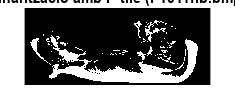

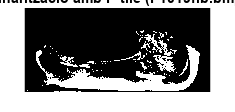

    [f c] = size(J);
    [h, ~] = imhist(J);
    p = h/(f*c);
    j = 1;
    count = 0;
    while (j <= 256) & (count < 0.8)
        count = count + p(j);
        j = j + 1;
    end
    llindar_llonza = j;
    greix = J > llindar_llonza;
    imshow(greix), title('Binarització amb P-tile (' + convertCharsToStrings(a(i).name) + ')')

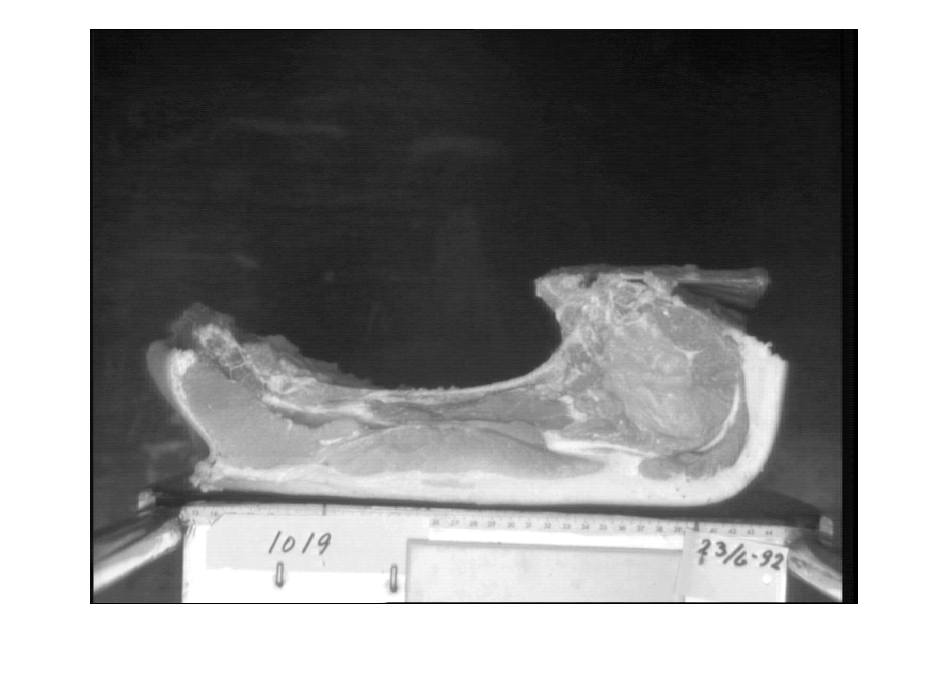

    figure


    size_greix = sum(sum(greix));
    percentatge_ptile = j/256;

    percentatge_ptile(i,1) = percentatge_ptile;
end

#### Generador de la taula

T = table(noms', percentatges_manuals, percentatges_auto, percentatges_otsu, percentatge_ptile, 'VariableNames', {'Names', 'Manual', 'Auto', 'Otsu', 'P-tile'})

T = 2×5 table
          Names           Manual     Auto     Otsu    P-tile 
    __________________    ______    ______    ____    _______

    {["F1011flb.bmp"]}    27.832    29.087    NaN     0.69531
    {["F1019flb.bmp"]}    23.567    33.032    100     0.69531
